# SDR

Generate IOT signals

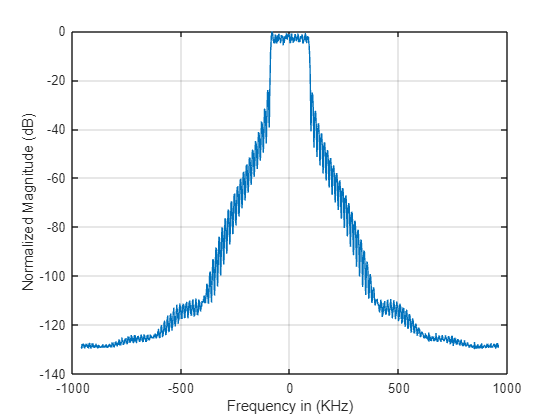

n_devices = 6;

[waveform,Fs] = Generate_NBiot();
Plot_Spectrum(waveform,Fs);

Fs_up = 2*200e3*7;
signal = waveform;
up_factor = ceil(Fs_up/Fs);
upsampled_sig = upsample(signal,up_factor);
% TX_filter = load('LS_512.mat');
% TX_filter_LS= TX_filter.Coeffs;

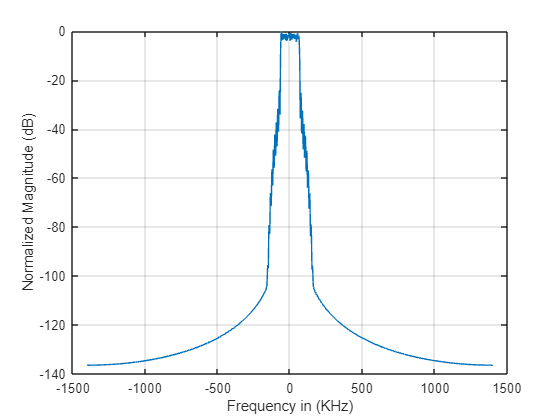

filtered_upsampled_sig_LS = filter(test_filter,upsampled_sig);
% F_new = linspace(2*F(2),2*F(end)+1,length(filtered_upsampled_sig_LS));
Plot_Spectrum(filtered_upsampled_sig_LS,Fs_up);

% % F_new = 2*F(1): 937.5:2*F(end)+937.5;
% filtered_upsampled_sig_LS_fft = abs(fftshift(fft(filtered_upsampled_sig_LS)))
% 
% figure
% % hold on;
% plot(F_new/1e3,(20*log10(filtered_upsampled_sig_LS_fft)),Color='b')
% xlim([-800,800])
% plot(F/1e3,20*log10(signal),Color='r')
% xlabel('Frequency in (KHz)')
% ylabel('Normalized Magnitude (dB)')
% xlim([-1885 1885])
% ylim([-140 0])
% legend('filtered','original')
% hold off;

spectrumAnalyzer = dsp.SpectrumAnalyzer(1);
spectrumAnalyzer.SampleRate = Fs;
spectrumAnalyzer(filtered_upsampled_sig_LS);

TX_filter_equiripple = Eq_Filt;

Unrecognized function or variable 'Eq_Filt'.

filtered_upsampled_sig_Eq = filter(TX_filter_equiripple,1,upsampled_sig);
% F_new = linspace(2*F(2),2*F(end)+1,length(filtered_upsampled_sig_Eq));
% F_new = 2*F(1): 937.5:2*F(end)+937.5;
% figure;
% hold on;
% plot(F_new/1e3,(20*log10(filtered_upsampled_sig_Eq)))
% plot(F/1e3,20*log10(signal))
% xlabel('Frequency in (KHz)')
% ylabel('Normalized Magnitude (dB)')
% xlim([-1700 1700])
% legend('filtered','original')
% hold off;

spectrumAnalyzer = dsp.SpectrumAnalyzer(1);
spectrumAnalyzer.SampleRate = Fs;
spectrumAnalyzer(filtered_upsampled_sig_Eq)

TX_filter_Gaussian = Gaussian_Filt;
filtered_upsampled_sig_Gaussian = filter(TX_filter_Gaussian,1,upsampled_sig);
spectrumAnalyzer = dsp.SpectrumAnalyzer(1);
spectrumAnalyzer.SampleRate = Fs;
spectrumAnalyzer(filtered_upsampled_sig_Gaussian)
% F_new = linspace(2*F(2),2*F(end)+1,length(filtered_upsampled_sig_Gaussian));
% F_new = 2*F(1): 937.5:2*F(end)+937.5;
% figure;
% hold on;
% plot(F_new/1e3,(20*log10(filtered_upsampled_sig_Gaussian)))
% plot(F/1e3,20*log10(signal))
% xlabel('Frequency in (KHz)')
% ylabel('Normalized Magnitude (dB)')
% xlim([-1700 1700])
% legend('filtered','original')
% hold off;

% figure;
% hold on;
% plot(F_new/1e3,(20*log10(filtered_upsampled_sig_LS)),Color='b')
% plot(F_new/1e3,(20*log10(filtered_upsampled_sig_Eq)),Color='r')
% plot(F_new/1e3,(20*log10(filtered_upsampled_sig_Gaussian)),Color='g')
% 
% legend('Least-Sqaures','Equiripple','Gaussian')
% ylim([-140 0])
% hold off;

%Compare Spectrums 
% %Filter LS
% sig_LS_fft = fft(filtered_upsampled_sig_LS,length(filtered_upsampled_sig_LS));
% fftshift(sig_LS_fft);
% sig_fft_log_LS = 20*log10(abs(fftshift(sig_LS_fft)));
% plot(F_new,sig_fft_log_LS)
% ylim([-90 50])
%Filter Eq
% sig_Eq_fft = fft(filtered_upsampled_sig_Eq,length(filtered_upsampled_sig_Eq));

% fftshift(sig_Eq_fft);
% sig_fft_log_Eq = 20*log10(abs(fftshift(sig_Eq_fft)));
% plot(F_new,sig_fft_log_Eq)
% ylim([-90 50])
%Filter Gaussian
% sig_Gaussian_fft = fft(filtered_upsampled_sig_Gaussian,length(filtered_upsampled_sig_Gaussian));
% fftshift(sig_Gaussian_fft);
% sig_fft_log_Gaussian = 20*log10(abs(fftshift(sig_Gaussian_fft)));
% plot(F_new,sig_fft_log_Gaussian)
% ylim([-90 50])

filtered_upsampled_sig_l512 = filter(ls_512,1,upsampled_sig);
spectrumAnalyzer = dsp.SpectrumAnalyzer(1);
spectrumAnalyzer.SampleRate = Fs;
spectrumAnalyzer(filtered_upsampled_sig_l512)
% F_new = linspace(2*F(2),2*F(end)+1,length(filtered_upsampled_sig_l512));
% F_new = 2*F(1): 937.5:2*F(end)+937.5;
% figure;
% hold on;
% plot(F_new/1e3,(20*log10(filtered_upsampled_sig_l512)))
% plot(F/1e3,20*log10(signal))
% xlabel('Frequency in (KHz)')
% ylabel('Normalized Magnitude (dB)')
% xlim([-1700 1700])
% legend('filtered','original')
% hold off;

% %Filter ls 512
% sig_l512_fft = fft(filtered_upsampled_sig_l512,length(filtered_upsampled_sig_l512));
% fftshift(sig_l512_fft);
% sig_fft_log_l512 = 20*log10(abs(fftshift(sig_l512_fft)));
% plot(F_new,sig_fft_log_l512)
% ylim([-90 50])

filtered_upsampled_sig_eq500 = filter(Eq_512,1,upsampled_sig);
spectrumAnalyzer = dsp.SpectrumAnalyzer(1);
spectrumAnalyzer.SampleRate = Fs;
spectrumAnalyzer(filtered_upsampled_sig_eq500)
% F_new = linspace(2*F(2),2*F(end)+1,length(filtered_upsampled_sig_eq500));
% F_new = 2*F(1): 937.5:2*F(end)+937.5;
% figure;
% hold on;
% plot(F_new/1e3,(20*log10(filtered_upsampled_sig_eq500)))
% plot(F/1e3,20*log10(signal))
% xlabel('Frequency in (KHz)')
% ylabel('Normalized Magnitude (dB)')
% xlim([-1700 1700])
% legend('filtered','original')
% hold off;

% %Filter eq500
% sig_eq500_fft = fft(filtered_upsampled_sig_eq500,length(filtered_upsampled_sig_eq500));
% fftshift(sig_eq500_fft);
% sig_fft_log_eq500 = 20*log10(abs(fftshift(sig_eq500_fft)));
% plot(F_new,sig_fft_log_eq500)
% ylim([-90 50])

filtered_upsampled_sig_Gaussian512 = filter(Gaussian_512.Coeffs,1,upsampled_sig);
spectrumAnalyzer = dsp.SpectrumAnalyzer(1);
spectrumAnalyzer.SampleRate = Fs;
spectrumAnalyzer(filtered_upsampled_sig_Gaussian512)
% F_new = linspace(2*F(2),2*F(end)+1,length(filtered_upsampled_sig_Gaussian512));
% F_new = 2*F(1): 937.5:2*F(end)+937.5;
% figure;
% hold on;
% plot(F_new/1e3,(20*log10(filtered_upsampled_sig_Gaussian512)))
% plot(F/1e3,20*log10(signal))
% xlabel('Frequency in (KHz)')
% ylabel('Normalized Magnitude (dB)')
% xlim([-1700 1700])
% legend('filtered','original')
% hold off;

%Filter ls 512
% sig_Gaussian512_fft = fft(filtered_upsampled_sig_eq500,length(filtered_upsampled_sig_Gaussian512));
% fftshift(sig_Gaussian512_fft);
% sig_fft_log_Gaussian512 = 20*log10(abs(fftshift(sig_Gaussian512_fft)));
% plot(F_new,sig_fft_log_eq500)
% ylim([-90 50])

Up Conversion

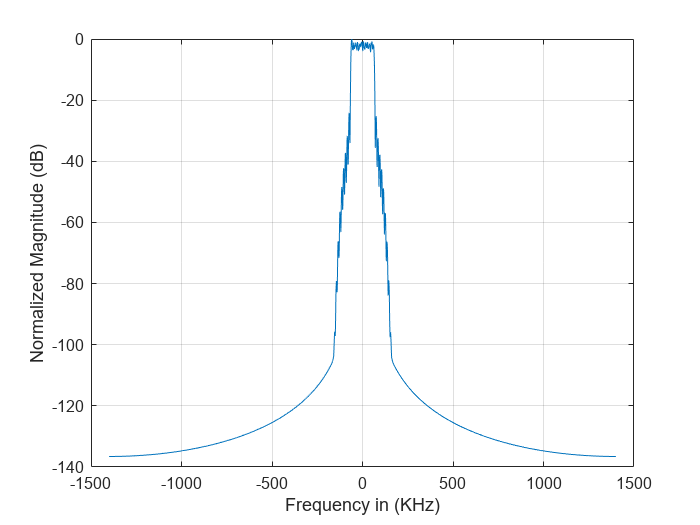

filtered_upsampled_sig_LS =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


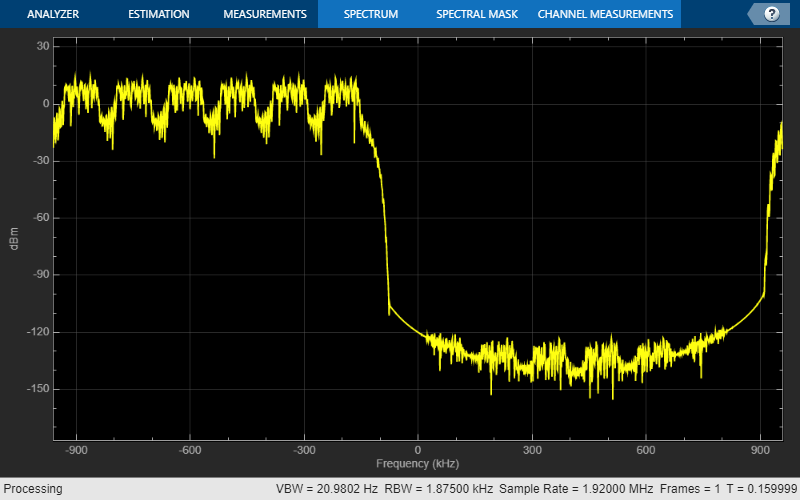

freqs = [290 490 690 890 1090 1290] * 1e3;
[sig_upConverted] = UpConversion(filtered_upsampled_sig_LS,freqs,Fs_up);
Plot_Spectrum(filtered_upsampled_sig_LS,Fs_up);

Down Convertion

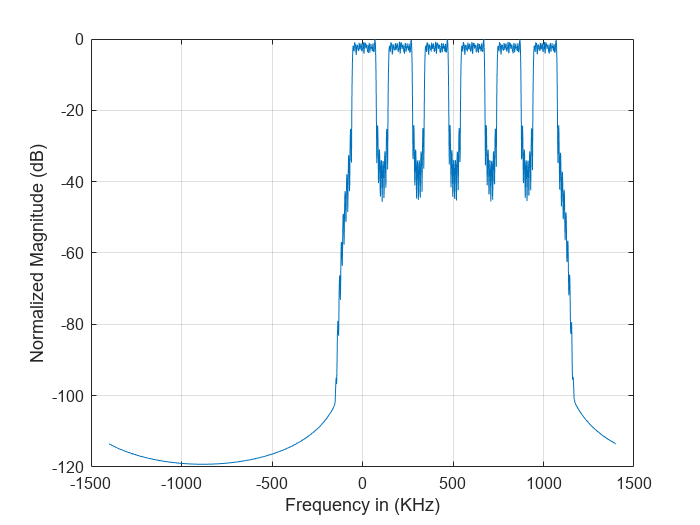

sigs_downConverted = DownConversion(sig_upConverted,freqs,Fs);
Plot_Spectrum(sigs_downConverted(1,:),Fs_up)

spectrumAnalyzer = dsp.SpectrumAnalyzer(1);
spectrumAnalyzer.SampleRate = Fs;
spectrumAnalyzer(sigs_downConverted(1,:)')

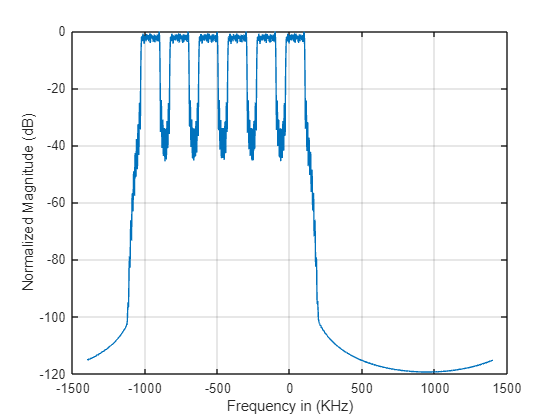



Plot_Spectrum(sigs_downConverted(6,:),Fs_up)

Filter & Down Sampling

%read filters
% fs = 2800 K
%fc 90K
%fpass 90k
%fstop 110k;

LS_256_Rx = load('LS_256_Rx.mat');
LS_256_Rx=LS_256_Rx.Coeffs;
LS_512_Rx = load('LS_512_Rx.mat');
LS_512_Rx=LS_512_Rx.Coeffs;         
Eq_256_Rx = load('Eq_256_Rx.mat');
Eq_256_Rx=Eq_256_Rx.Coeffs;
Eq_512_Rx = load('Eq_512_Rx.mat');
Eq_512_Rx=Eq_512_Rx.Coeffs;
FT_512_Rx = load('FlatTop_512_Rx.mat');
FT_512_Rx=FT_512_Rx.Coeffs;
Hamming_512_Rx = load('Hammin_512_Rx.mat');
Hamming_512_Rx=Hamming_512_Rx.Coeffs;

Filter 1 : Least Squares: Order 256

[signals_down_LS_256,Fs_down] = filter_fn(LS_256_Rx,sigs_downConverted,Fs_up);

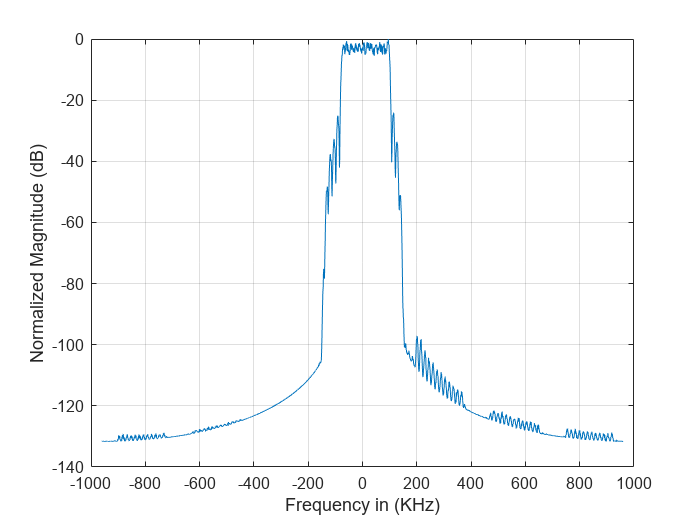

Plot_Spectrum(signals_down_LS_256(1,:),Fs_down)

Filter 2 : Least Squares: Order 512

[signals_down_LS_512,Fs_down] = filter_fn(LS_512_Rx,sigs_downConverted,Fs_up);

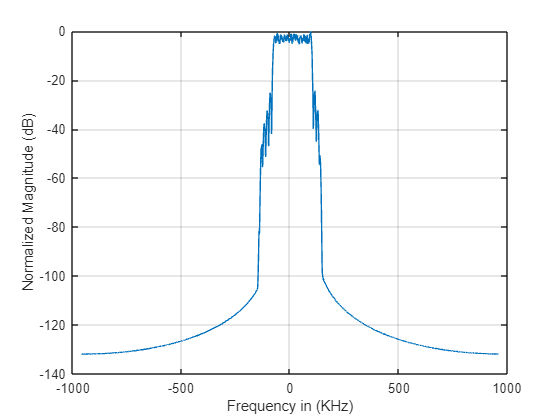

Plot_Spectrum(signals_down_LS_512(1,:),Fs_down)

Filter 3 : Eq Order 256

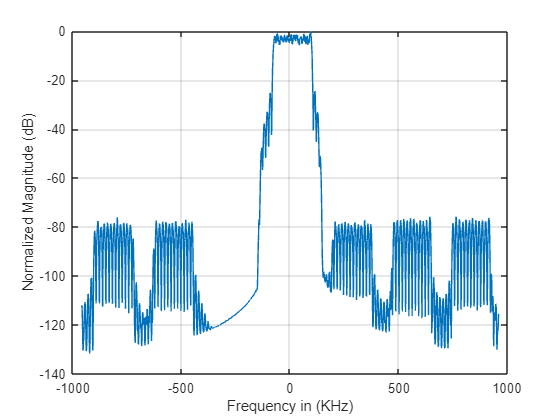

[signals_down_Eq_256,Fs_down] = filter_fn(Eq_256_Rx,sigs_downConverted,Fs_up);
Plot_Spectrum(signals_down_Eq_256(1,:),Fs_down)

Filter 4 : Eq Order 512

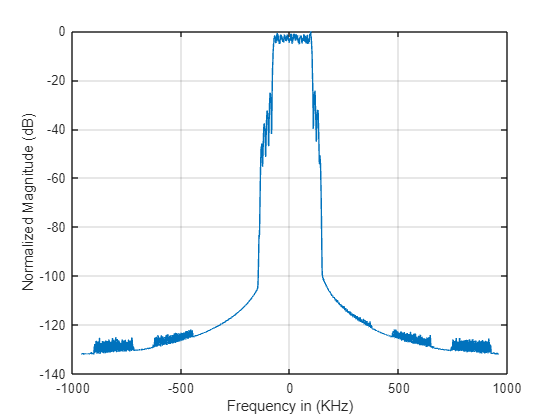

[signals_down_Eq_512,Fs_down] = filter_fn(Eq_512_Rx,sigs_downConverted,Fs_up);
Plot_Spectrum(signals_down_Eq_512(1,:),Fs_down)

Filter 5 : FlatTop Order 512

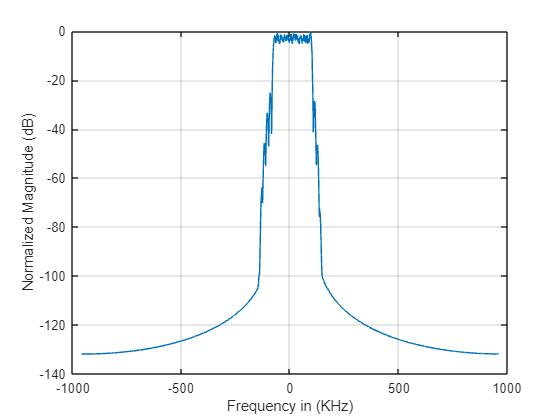

[signals_down_FT_512,Fs_down] = filter_fn(FT_512_Rx,sigs_downConverted,Fs_up);
Plot_Spectrum(signals_down_FT_512(1,:),Fs_down)

Filter 6 : Hammin Order 512

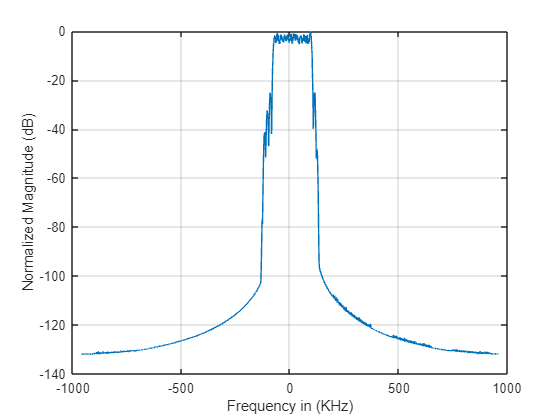

[signals_down_Hamming_512,Fs_down] = filter_fn(Hamming_512_Rx,sigs_downConverted,Fs_up);
Plot_Spectrum(signals_down_Hamming_512(1,:),Fs_down)

function [sig, Fs_down] = filter_fn(filter_coefficients,sigs_downConverted,Fs)
    Fs_down = 1920*10^3;
    down_Factor = ceil(Fs/Fs_down);
    % singals_down_LS_256=zeros(n_devices,21943);
    sig = [];
    n_devices = 6;
    for i=1:n_devices
        sig_filt = filter(filter_coefficients, 1,sigs_downConverted(i,:));
    %     plot(sig_filt)
        sig_down_sampled = downsample(sig_filt,down_Factor);
        sig=[sig; sig_down_sampled];
    end
end

Up Conversion Function 

function [up_conv_sig] = UpConversion(sig_time, frequencies,fs)
    n=length(sig_time);
    ts=1/fs;
    tt= 0:ts:ts*(n-1);
    I_carrs = zeros(length(frequencies),length(tt));
    up_conv_sigs=zeros(6,length(tt));
    for i = 1:length(frequencies)
%         this_carr = cos(2*pi*frequencies(i) * tt);
        this_carr = exp(1i*2*pi*frequencies(i) * tt);
        I_carrs(i,:)=this_carr;
        up_conv_sigs(i,:)=sig_time'.*this_carr;
    end

    up_conv_sig = sum(up_conv_sigs,1);


end

Down Convertion Function

function [down_conv_sigs] = DownConversion(sig_time, frequencies,fs)
    n=length(sig_time);
    ts=1/fs;
    tt= 0:ts:ts*(n-1);
    I_carrs = zeros(length(frequencies),length(tt));
    f=2/3;
    down_conv_sigs=zeros(6,length(tt));
    for i = 1:length(frequencies)
        this_carr = exp(-1i*2*pi*f*frequencies(i) * tt);
        I_carrs(i,:)=this_carr;
        down_conv_sigs(i,:)=sig_time.*this_carr;
    end

end